Load and print images:

% desk
sceneImage = imread('./clutteredDesk.jpg');

% template
boxImage = imread(['./elephant.jpg']);


figure(1), clf, imshow(boxImage)
figure(2), clf, imshow(sceneImage)

crop template image

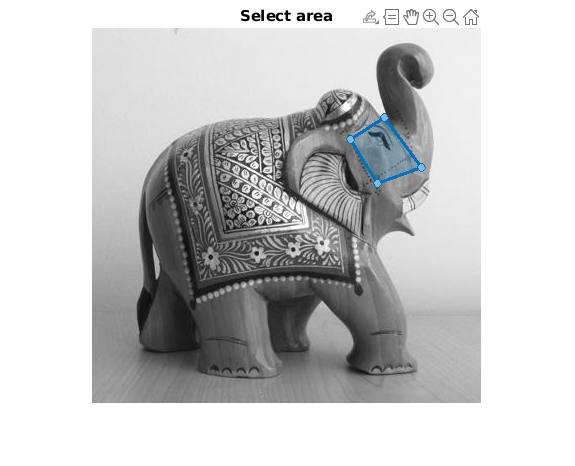

figure(1), clf, imshow(boxImage), title('Select area');
drewPolygon = drawpolygon();

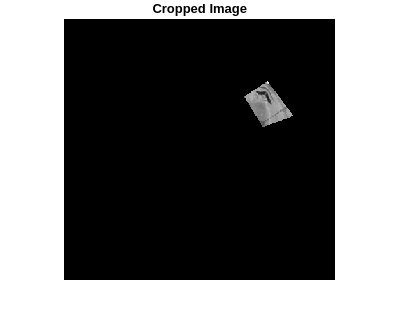

wait(drewPolygon); % wait to draw a polygon

poliPosition = drewPolygon.Position;
% in the example they used a binary mask
bwMask = poly2mask(poliPosition(:,1), ...
    poliPosition(:,2), ...
    size(boxImage, 1), ...
    size(boxImage, 2));
croppedImage = boxImage;
croppedImage(repmat(~bwMask, [1, 1, size(boxImage, 3)])) = 0;

figure(2), clf, imshow(croppedImage), title('Cropped Image');

Now keypoints

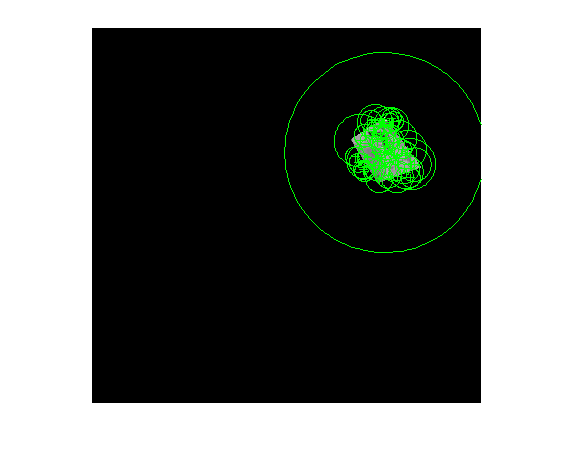

boxImage = croppedImage;
%% keypoint detection
boxPoints = detectSURFFeatures(boxImage, "MetricThreshold", 80, "NumOctaves", 8);
scenePoints = detectSURFFeatures(sceneImage, "MetricThreshold", 80, "NumOctaves", 8);

figure(1), clf
imshow(boxImage), hold on
plot(selectStrongest(boxPoints,100)), hold off

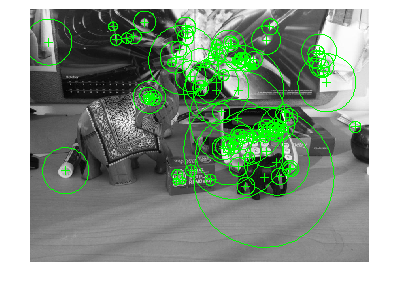


figure(2), clf
imshow(sceneImage), hold on
plot(selectStrongest(scenePoints,100)), hold off

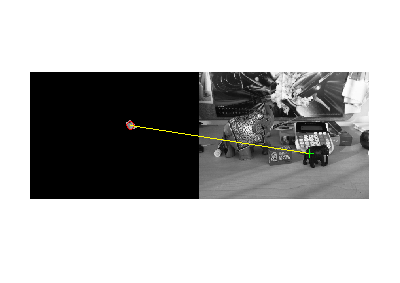


%% keypoint description
[boxFeatures, boxPoints]=extractFeatures(boxImage, boxPoints);
[sceneFeatures, scenePoints]=extractFeatures(sceneImage, scenePoints);

%% feature matching
boxPairs = matchFeatures(boxFeatures, sceneFeatures);
matchedBoxPoints = boxPoints(boxPairs(:,1),:);
matchedScenePoints = scenePoints(boxPairs(:,2),:);
showMatchedFeatures(boxImage, sceneImage, matchedBoxPoints, ...
    matchedScenePoints, 'montage');


%% geometric consistency check
[tform, inlierBoxPoints, inlierScenePoints]=...
    estimateGeometricTransform(matchedBoxPoints,...
    matchedScenePoints,'affine');

Error using vision.internal.geotrans.algEstimateGeometricTransform>checkRuntimeStatus
matchedPoints1 and matchedPoints2 do not have enough points. The number of points in each set must be at least 3.

Error in vision.internal.geotrans.algEstimateGeometricTransform (line 72)
    checkRuntimeStatus(statusCode, status, sampleSize);

Error in 

showMatchedFeatures(boxImage, sceneImage, inlierBoxPoints, ...
    inlierScenePoints, 'montage');